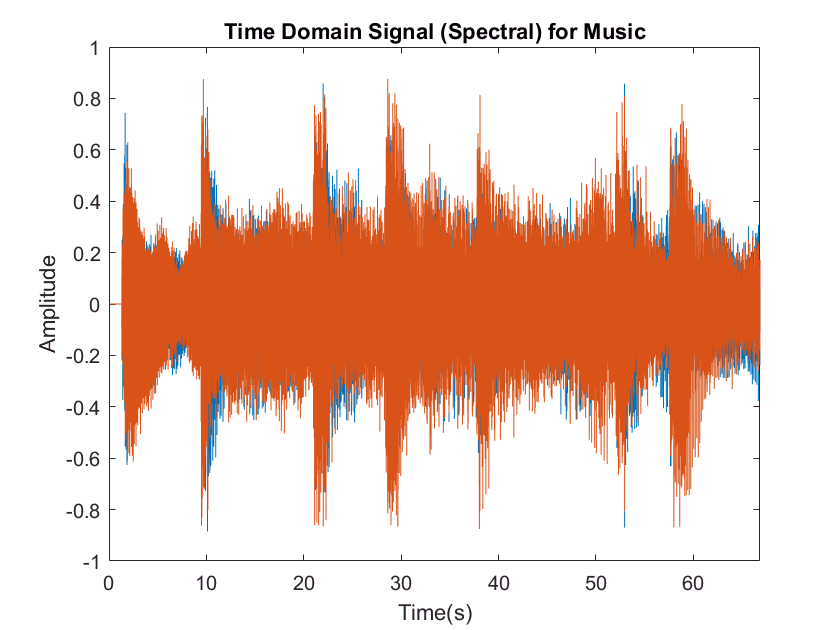

%insert Music File Function
[FileMus, SourceFile] = uigetfile('*.mp3', 'Insert Music');%Choosing the directory of music's file
Music = [SourceFile, FileMus];
[x, fs] = audioread(Music);
sound(x, fs);

%variable initialization
P = length(x);%save lenght of x in P
t = 10*(0:1/fs:(P-1)/fs); %time function
SpectralGraph = figure;%variable for figure (temporary store var)
plot(t, x);
title('Time Domain Signal (Spectral) for Music')
xlabel('Time(s)');
ylabel('Amplitude');
xlim([0 t(end)]);%becaue the lenght of time in music files cannot be determined
                 %the limit of x is until the end of music files.
saveas(SpectralGraph, 'SpectralofMusic.jpg');%save to pic file format

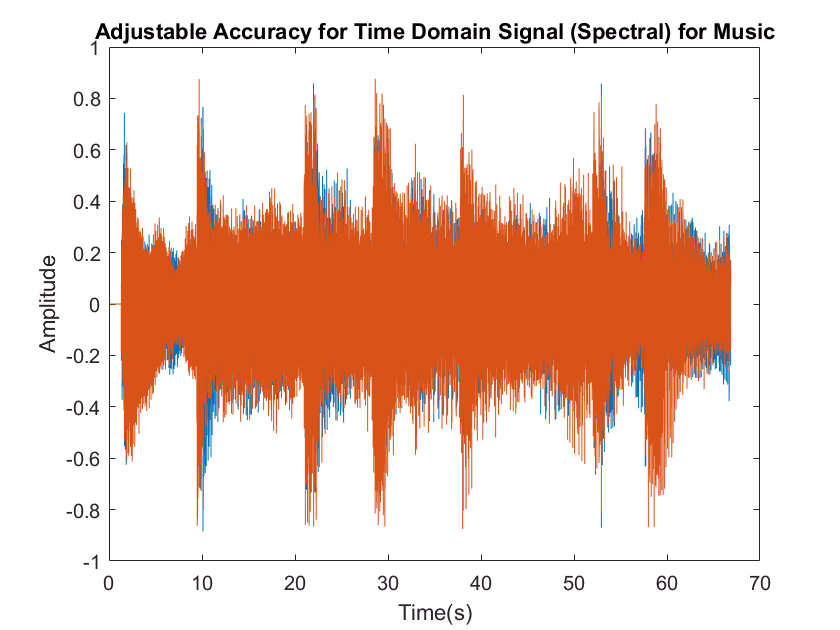

%accuracy
song = x(2.45e4:3.10e4);%melakukan adjustment pada fungsi ketelitian dengan adjust waktu
t = 10*(0:1/fs:(P-1)/fs);
AccuracySpectral = figure;
plot(t, x);
title('Adjustable Accuracy for Time Domain Signal (Spectral) for Music')
xlabel('Time(s)');
ylabel('Amplitude');
saveas(AccuracySpectral, 'AccuracySpectral.jpg');

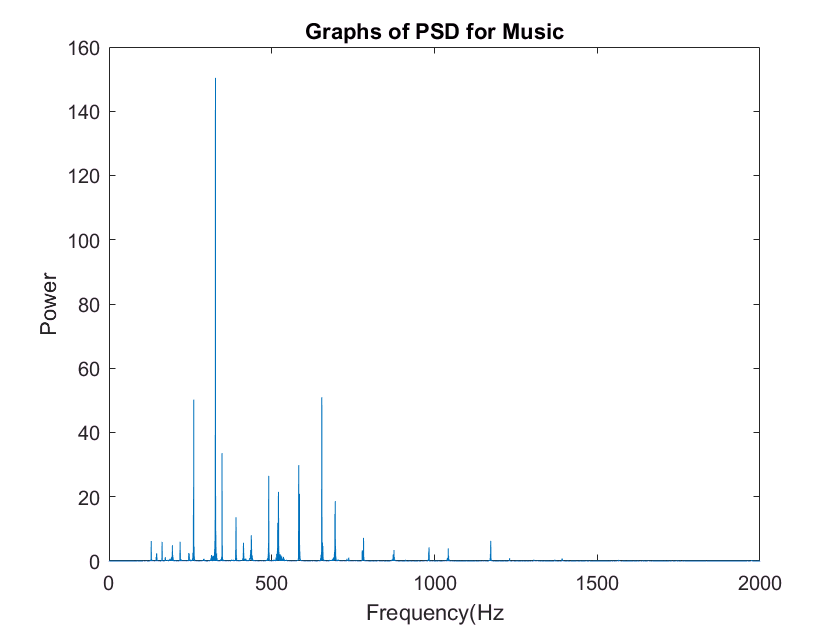


%convert to frequency
n = pow2(nextpow2(l));
y = fft(x, n);%FFT with fourier calc
%psd graph:
freq = (0:n-1)*(fs/n);
Pow = abs(y).^2/n; %PSD graph's power
PSDGraph = figure;

plot(f(1:floor(n/2)), Pow(1:floor(n/2)));

title('Graphs of PSD for Music');
xlabel('Frequency(Hz');
ylabel('Power');
xlim([0 2000]);%limit until 2000 HZ
saveas(PSDGraph, 'PSDofMusic.jpg');